## `Additív fa táblázatból:`

`Megnézzük, hogy a Bioinformatics addon le van-e töltve.`

if ~matlab.addons.isAddonEnabled("Bioinformatics Toolbox")
    error('Nincs letöltve a Bioinformatics Toolbox addon');
end

`Betöltjük a táblázatot.`

    [fajl, eleresiut] = uigetfile('*.mat', 'Válaszd ki a táblázatot tartalmazó .mat fájlt!');
    if fajl == 0
        error('Nem választottál ki fájlt.');
    end
    betoltes = load(fullfile(eleresiut, fajl));
        valtozok = fieldnames(betoltes);
        [idx, ok] = listdlg('ListString', valtozok, 'Name', 'Melyik változó a táblázat?');
        if ok
            tablazat = betoltes.(valtozok{idx});
        else
            error('Nem választottál változót.');
        end

`Ezt konvertáljuk Array típusra, hogy a tobbi függvényt lehessen alkalmazni rajta.`

tablazatArray=table2array(tablazat);

`Legeneráljuk a távolságok mátrixot.`

tavolsagok=pdist2(tablazatArray,tablazatArray,@sorensenDice);

`Majd legeneráljuk az additív fát, a távolságokkal. A neveket az eredeti táblázatból vesszük.`

fa=seqneighjoin(tavolsagok,"equivar",tablazat.Properties.RowNames);

`Töröljük memóriából a már felesleges változókat`

clearvars -except fa

`Majd megtekintjük a fát.`

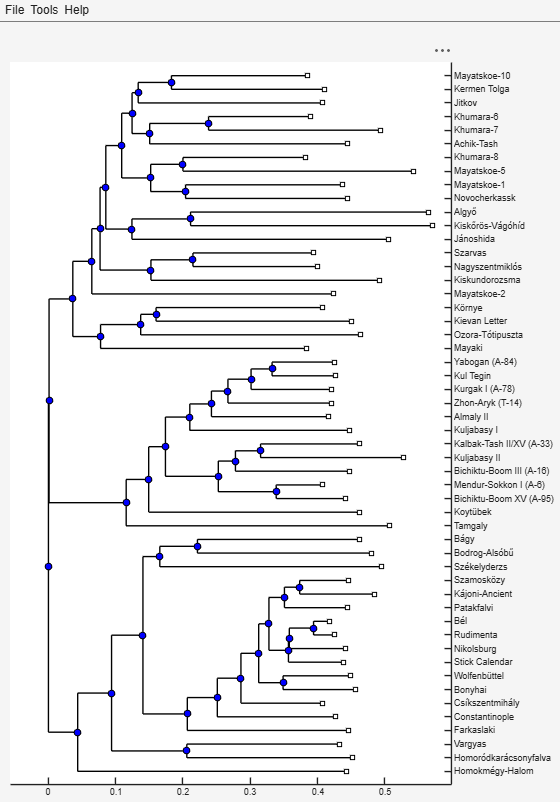

view(fa);